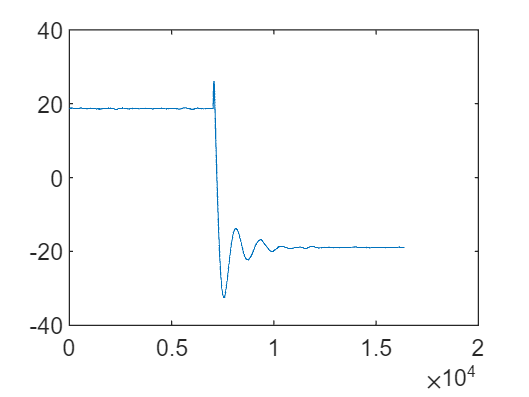

close all
clear

load("Edukit_Step Response Rotor Angle (degrees)__05-08-2023_17-35.mat")

[mean_pendulum_angle]=calcola_media(pendulum_angle);
[mean_rotor_angle,t]=calcola_media(rotor_angle);

plot(mean_rotor_angle)

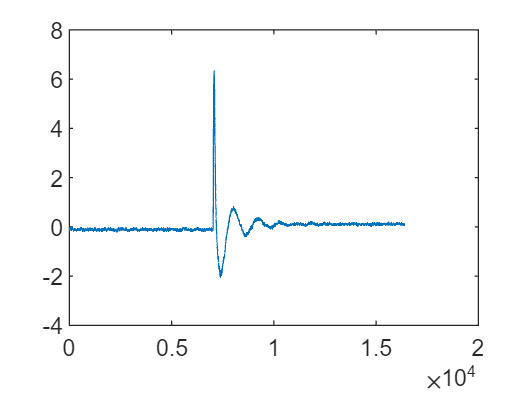

plot(mean_pendulum_angle)

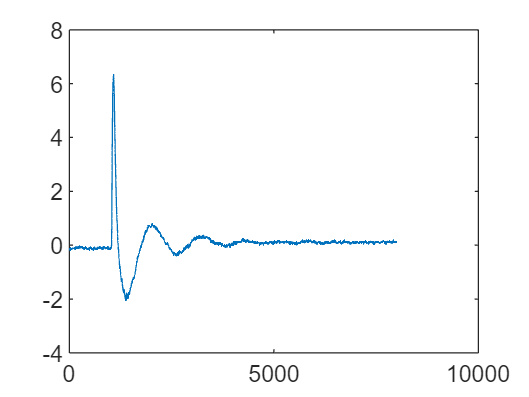


mean_rotor_angle=mean_rotor_angle(6000:14000);
mean_pendulum_angle=mean_pendulum_angle(6000:14000);
plot(mean_pendulum_angle')

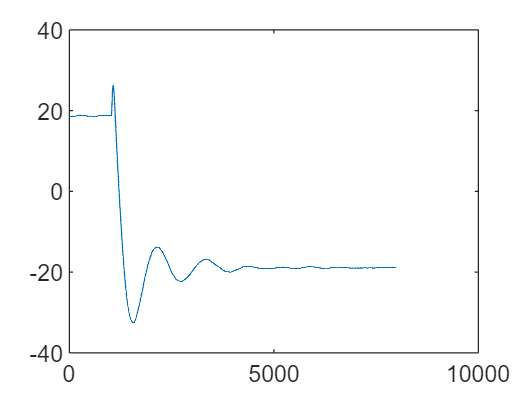

plot(mean_rotor_angle')


%Best performance for ham-wein with 5 poles 2 zeros and 3 breakpoints
%obtained with rotor angle between [0 40]. Otherwise with [-20 20] step
%input, the model doesn't reconstruct the correct dynamics.

IDENTICO a quello della cartella precedente